# Volume Annotation App

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension in mm
    0 300 % X dimension in mm
    0 150 % Z dimension in mm
    ];

## Create the app

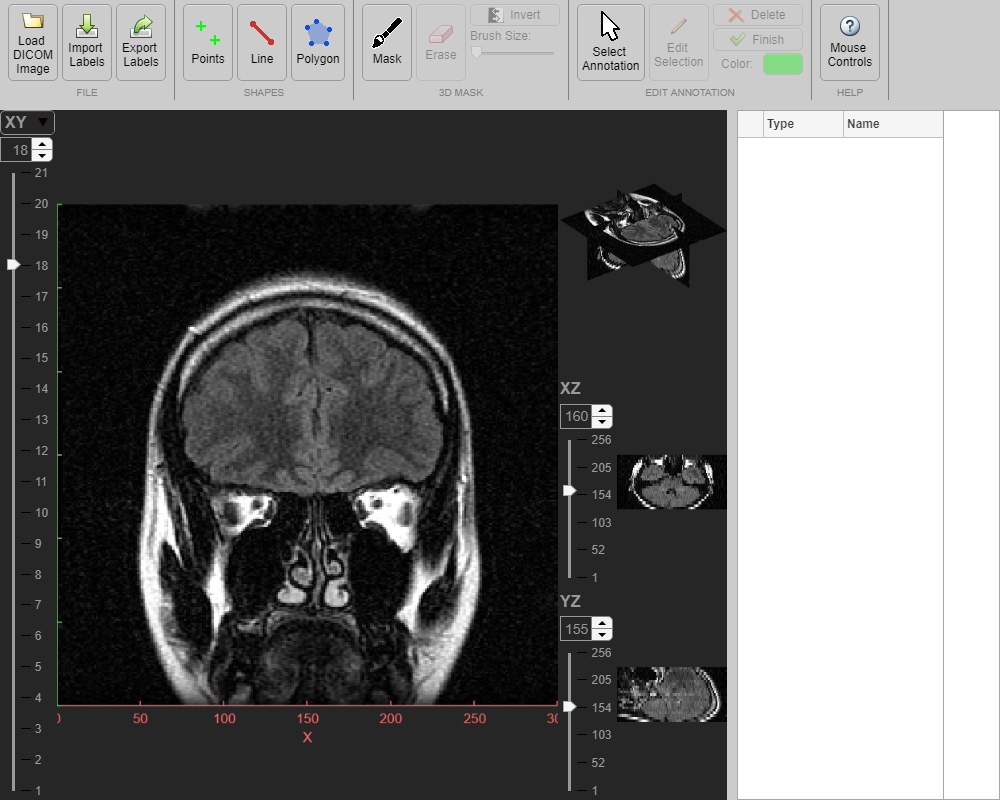

app = wt.apps.VolumeAnnotationApp('VolumeModel',volModel);

% Choose an interesting  slice 
app.AnnotationViewer.Slice3D = [160 155 18];

*Copyright 2018-2021 The MathWorks, Inc.*